## Caricamento dati

root = "C:\Users\trima\OneDrive - unime.it\Appunti Università\Appunti condivisi\00) Tirocinio\Trimarchi\V2G-with-Regression-Learner-and-LSTM-NN";
% Aggiungiamo il percorso degli script
addpath(root + "\Scripts");
%zone_id=1; %"Zone_509_Ponte Mammolo";
%zone_id=2; %"Zone_116_Trastevere";
%fzone_id=3; %"Zone_125";
%zone_id=4; %"Zone_705_Prenestino-Centocelle";;
%zone_id=5; %"Eur 1201"
%zone_id=6;
%zone_id=7; %"Zone_906_Arco_Di_Travertino"
%zone_id=8; % Zona 1016
%zone_id=9; %Zona 214 Trieste
%zone_id=10; % Zona 2004
zone_id=11; % Zona 2002
%zone_id=12; %Torvergata

% Usiamo uno script che vuole come parametro la root e la zona da caricare
data = load_datas(root,zone_id);

Dati per la zona "Zone2002_Tor di Quinto6" caricati correttamente.


## Costanti

num_lags = 50;
predittori = {'AAC_energy','precipprob','temp','windspeed', 'holiday_indicator'};
target = 'AAC_energy';
colonne_da_normalizzare = [predittori, target];

[data_norm, params_norm_datas] = normalize_zscore_2(data, colonne_da_normalizzare);

Normalizzazione Z-score completata sull'intero dataset.


data_norm_lags2 = create_lags_regression_learner(data_norm, num_lags, predittori, target);

Giorni totali: 58
Giorni consecutivi validi: 54
Righe totali create: 2484


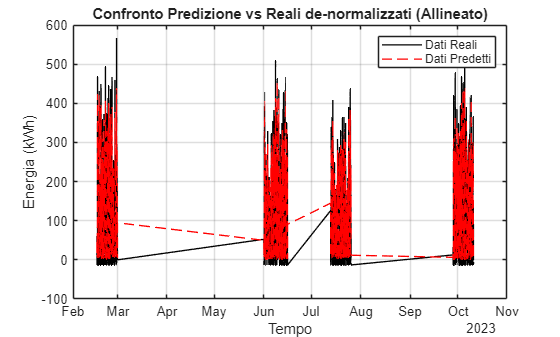

figura_predizione =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


dati_predizione = Ensemble_Bagged_Trees.predictFcn(data_norm_lags2);
figura_predizione = get_plot_RL(dati_predizione,data_norm_lags2.AAC_energy,params_norm,target,data_norm_lags2.time_vector)

indicators_pred = get_indicators(dati_predizione,data_norm_lags2.AAC_energy)

indicators_pred = struct with fields:
    RSquared: 0.8507
        RMSE: 0.3862
         MSE: 0.1491
        MAPE: 201.5471
         MAE: 0.2843
